# Test Axpy

This Live Script helps you test and visualize the performance of the simple implementation of the Axpy operation.

To gather the performance data, execute 

clear

system('make test_Axpy')

echo "5 32 1000 32" | ./driver_Axpy.x > output_data_Axpy.m


ans = 0

When completed, this creates output file 'output_data_Axpy.m' with the difference between your implementation and the reference implementation.

## Step 1a: Load timing data

output_data_Axpy

## Step 1b: Make sure you are getting the right answer

In output_data_Axpy.m, for each execution of Axpy data of how close the answer is to the answer attained by the reference implementation.  Here we look at the maximum difference over all experiments.  This should be somewhere on the order of $ 10^{-11} $ or smaller.  Notice that you can expect some difference between the two implementations, due to round-off error and the order in which computations are performed.

MaxAbsDiff = max( abs( data_Axpy( :, 3 ) ) )

MaxAbsDiff = 0

It appears all is fine


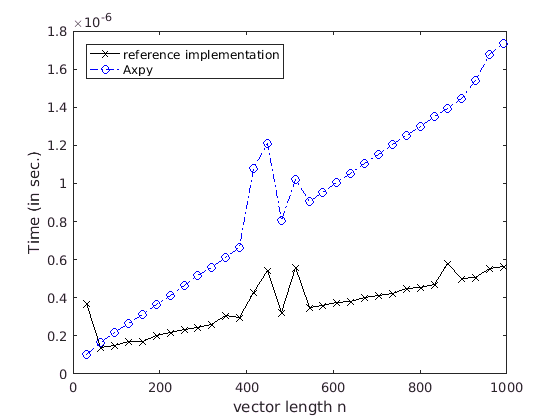

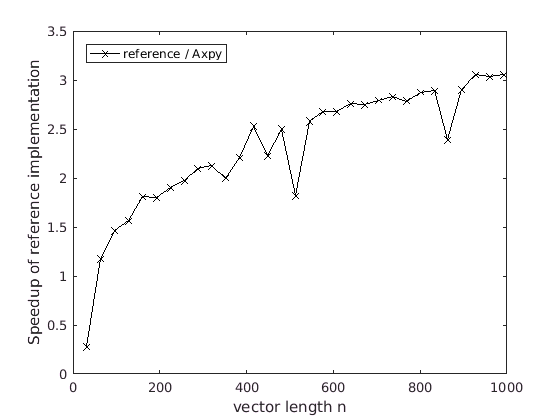

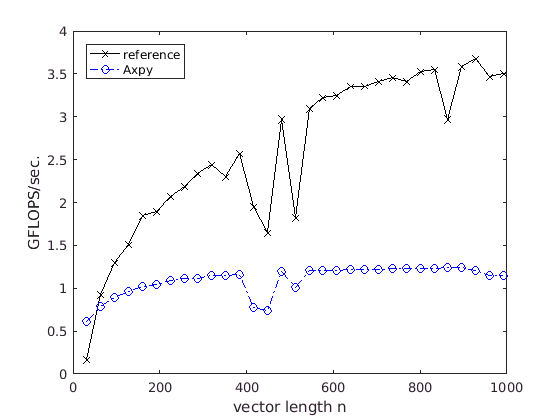

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

For Axpy, if the vector is of length n, then there are O(n) operations for O(n) inputs. Hence, it is a memory-bound operation, and we do not plot the performance of this operation.